# **Examen parcial 1: Control y Sistemas 2025**

## **Requerimientos de Ingeniería**

Se recuperan las señales de dos sensores x_c(t) y x_r(t). La primera es una onda senoidal y la segunda una onda rectangular. Ambas fueron tratadas con un filtro antialiasing pero las mismas acarrean unas perturbaciones particulares que se quieren remover. Debemos realizar el tratamiento correspondiente con el método oversampling para lograr ingresarlas a un sistema de cómputo discreto (procesador, DSP) donde se desea realizar operaciones con la información que traen. Para ello es necesario asegurarse de remover el ruido que tienen y hacerlo logrando mantener la forma de la onda, acotar el desfasaje del resultado y tener una buena relación ruido-señal. Buscamos que el procesador realice los cálculos confiando que la señales que proveemos traen la información real.   

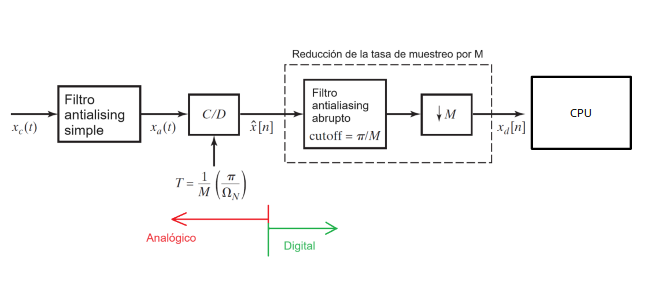

## **Antes de iniciar los cálculos y el diseño**

Describa lo que interpreta del requerimiento de la aplicación y cómo procederá para resolver reducido a tres simples pasos de manera descriptiva y simple.  

**Lo que se pide es que se filtren dos señales analógicas que han pasado por un filtro analógico antialiasing pero que aún tienen ruido. Esto sin producir distorsión de forma o excesivo retraso y que el filtrado sea lo suficientemente bueno como para que el SNR sea alto y se distinga bien la señal.**

**Pasos:**

**1 -  Muestrear las señales de entrada con una frecuencia fs suficiente.**

**2 - Aplicar un filtro digital abrupto sobre la señal de muestreada.**

**3 - Decimar sobre la señal obtenida para preservar solo la información útil.**

## Descripción de las señales

Una de las señales tiene una frecuencia máxima de 1 Hz, la otra de 5Hz; y se desea usar un filtro antialiasing analógico **simple** [con atenuación de -3 dB en 100 Hz y -60 dB en 200 Hz (no es necesario diseñar este filtro analógico)]. 

Ambas señales son interferidas por ruidos distintos. La señal senoidal acarrea una componente de ruido senoidal del 50Hz. En cambio la señal rectangular es atacada por un ruido gaussiano tal que la relación señal-ruido entre la señal rectangular y el ruido es de 15dB.

clc
clear
close all
%% Frecuencia de signals
frequency_xc = 1;        % [Hz] frequency of signal 1
frequency_xr = 5;       % [Hz] frequency of signal 2
frequency_noise = 50;      % [Hz]
% Definir SNR ruido onda rectangular (en dB)
SNR_dB = 1;

## Muestreo y señales

## Determine la mínima frecuencia de muestreo

Necesitamos que la etapa de muestreo evite errores por aliasing y que podamos recuperar la información que tiene la señal.

**La señal útil se encuentra en la banda límitada por 5 Hz. El ruido de banda ancha (gaussiano) podemos asumir que se encuentra lo suficientemente atenuado luego de los 200 Hz por el filtro antialiasing analógico. Se sugiere utilizar una frecuencia de muestreo de 300 Hz. Entonces, el ruido de banda ancha en el rango de 100 Hz a 200 Hz, que es ruido atenuado por el filtro antialiasing, va a estar solapado, pero no va a haber solapamiento del ruido con la señal. Aún se preservará el ruido de línea a 50 Hz sin atenuación.**

**Otra opción era utilizar una frecuencia de muestreo de 200 Hz (fstop del filtro antialiasing) + 10 Hz (5 Hz mas que la señal útil para que la señal útil no caigan justo al borde derecho del espectro de frecuencia luego de la decimación). Pero en el rango de 5 Hz a 105 Hz va a existir solapamiento de ruido de banda ancha atenuado por el filtro antialiasing (lo que se rebate) con el ruido de banda ancha sin atenuar entre 5 Hz y 100 Hz.  **

## Declaración de parámetros de muestreo

## Parámetros de las señal

sampling_rate = 300;       % [Hz] how often the signal is sampled
fs = sampling_rate

fs = 300

## Rango de tiempo y vector de tiempo

start_time = 0;         % [s] beginning of the time window
end_time = 1;         % [s] end of the time window

t = start_time : 1/sampling_rate : end_time;  % [s] time points at which the signal is sampled

## Construcción de las señales y ruidos

## Señal 1, señal 2 y ruidos

Construya usando su vector de tiempo las señales senoidales y rectangular. Construya los ruidos y apliquelos a las señales originales.


% 2π * frequency [rad/s] * time [s] → [rad] → sin(...) → unitless amplitude
signal_xc = sin(2 * pi * frequency_xc * t);         % [1] sine wave values (unitless amplitude)
signal_xr = square(2 * pi * frequency_xr * t);

% ruido_xc y ruido_xr
noise_xc = sin(2*pi*frequency_noise*t)

noise_xc =          0    0.8660    0.8660    0.0000   -0.8660   -0.8660   -0.0000    0.8660    0.8660   -0.0000   -0.8660   -0.8660   -0.0000    0.8660    0.8660   -0.0000   -0.8660   -0.8660    0.0000    0.8660    0.8660   -0.0000   -0.8660   -0.8660   -0.0000    0.8660    0.8660   -0.0000   -0.8660   -0.8660    0.0000    0.8660    0.8660   -0.0000   -0.8660   -0.8660    0.0000    0.8660    0.8660   -0.0000   -0.8660   -0.8660    0.0000    0.8660    0.8660   -0.0000   -0.8660   -0.8660   -0.0000    0.8660


signal_noise_xr = awgn(signal_xr, SNR_dB, 'measured')

signal_noise_xr =     0.6824    0.6153    1.6946    1.7276    2.0234    0.0330    0.8787    1.5839   -0.1528    2.7172    1.2079    0.5142    1.9205    1.3361    1.0974    0.3938   -0.5734    0.1412    0.4246    1.4033    1.5477    0.3001    1.7381    1.5948    0.8881    0.1522    1.7950    0.8844    0.0967    1.2249   -0.5334   -2.3027    0.6634   -2.9153   -2.4574    0.0909   -0.7102   -1.3823   -0.9897   -0.3482   -1.7736   -0.1728   -0.3785   -1.0402   -0.8296   -1.5604   -1.7635   -1.3464   -0.0833   -1.2137



% Calcular 
signal_noise_xc = signal_xc + noise_xc;     % [1] signal with additional noise
%signal_noise_xr = signal_xr;	    % [1] signal with additional noise

## Plot de señales en el dominio del tiempo

Realice un plot de la señales sin la perturbación, el ruido y la señal con la perturbación agregada. 

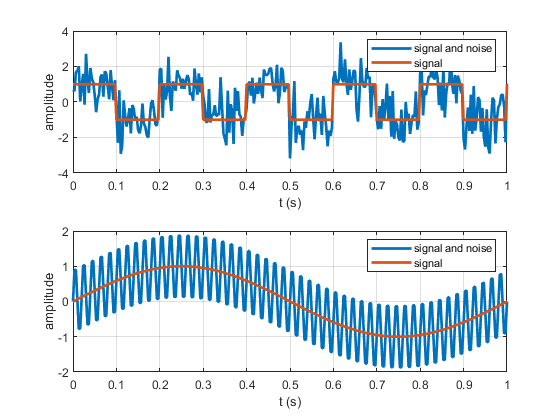

figure
hold on
subplot(2,1,1)
plot(t, [signal_noise_xr; signal_xr], 'linewidth', 2)
xlabel('t (s)')
ylabel('amplitude')
legend('signal and noise', 'signal')
grid on
subplot(2,1,2)
plot(t, [signal_noise_xc; signal_xc], 'linewidth', 2)
xlabel('t (s)')
ylabel('amplitude')
legend('signal and noise', 'signal')
grid on

## Plot de señales en el dominio de la frecuencia

Realice un plot de la señales sin la perturbación agregada en el dominio de la frecuencia para lograr ver sus componentes. 

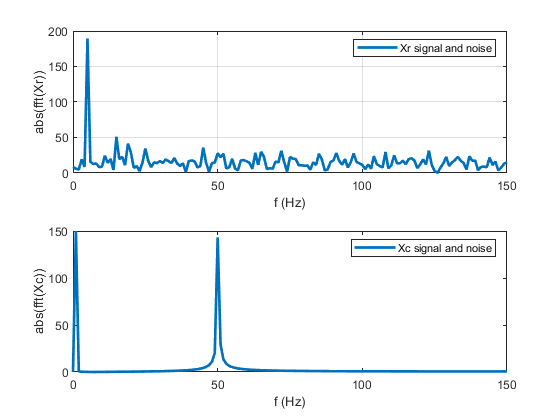

Xr = abs(fft(signal_noise_xr));
Xc = abs(fft(signal_noise_xc));
figure
subplot(2,1,1)
plot(linspace(0, fs/2, round(length(Xr)/2)), Xr(1:round(length(Xr)/2)), 'linewidth', 2);
xlabel('f (Hz)')
ylabel('abs(fft(Xr))')
legend('Xr signal and noise')
grid on
subplot(2,1,2)
plot(linspace(0, fs/2, round(length(Xc)/2)), Xc(1:round(length(Xc)/2)), 'linewidth', 2);
xlabel('f (Hz)')
ylabel('abs(fft(Xc))')
legend('Xc signal and noise')

## Conclusiones

***La señal tiene más información representada en el dominio del tiempo y o de la frecuencia?***

La señal senoidal con ruido esta bien expresada en el dominio de la frecuencia y puede condicionar qué filtro sería mas propio aplicar. La señal cuadrada tiene ruido en todas las frecuencias con lo cual sería adecuado un filtro específicado en el dominio del tiempo. Sin embargo en la señal cuadrada, también hay que preservar la suficiente cantidad de componentes de frecuencias para que quede bien representada.

*** Esto puede influir en la elección del filtro?***

Sí.

## Filtrado y Decimación

## Las características del decimador y del filtro digital que debe implementar

Deberá elegir entre alguna de las implementaciones de filtros posibles. Fundamente porque realizó dicha elección.

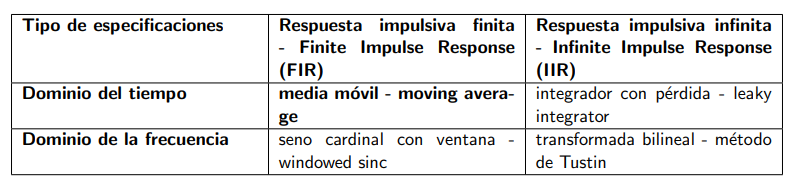

Para filtrar la señal senoidal se va a utilizar un filtro de media móvil que tenga un cero justo en la frecuencia del ruido de línea de 50 Hz. La frecuencia de corte del filtro será de 25 Hz, por encima de los 1Hz de la señal, entonces tampoco la va a atenuar apreciablemente.

Para filtrar la señal cuadrada también se va a utilizar un filtro de media móvil par que suavice lo suficiente el ruido de mas alta frecuencia sin comprometer mucho la señal.

## Diseño del filtro FIR onda senoidal

ord = round(fs/frequency_noise); % orden del filtro de media movil
b = ones(1, ord)/ord;
a = 1;
filtered_signal_xc = filter(b, a, signal_noise_xc);

## Polos, ceros y diagrama de bode

Realice un plot para ver ceros, polos y el diagrama de bode del filtro

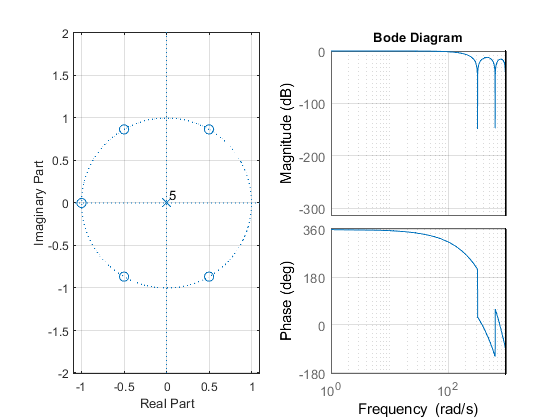

figure
subplot(1,2,1)
zplane(b,a)
grid on
subplot(1,2,2)
bode(filt(b, a, 1/sampling_rate))
grid on

## Decimación onda senoidal

Realice una decimación de la onda filtrada, elegiendo bien la nueva frecuencia de muestreo.

fs     = sampling_rate;
%fs_new = 75;
fmax   = 35;            % conserva la suf cantidad de armonicos de la señal cuadrada
fs_new = 2*fmax;
subsampled_filt_signal_xc = filtered_signal_xc(1:round(fs/fs_new):end);
subsampled_t = t(1:round(fs/fs_new):end);
round(fs/fs_new)

ans = 4

## Análisis en frecuencia y tiempo onda senoidal

Haga un plot en frecuencia de para ver si eliminó las componentes que buscaba eliminar. 

## Código análisis en frecuencia

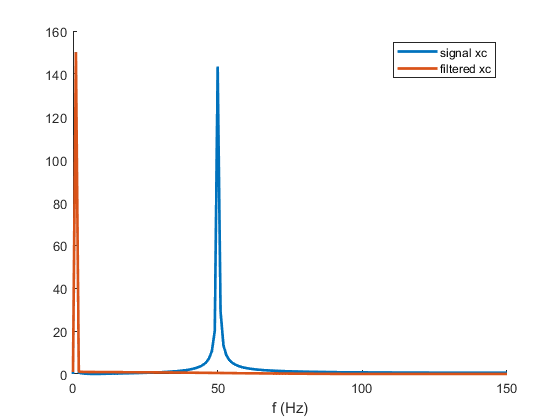


X = abs(fft(signal_noise_xc));
X_filt = abs(fft(filtered_signal_xc));
figure
hold on
plot(linspace(0, fs/2, round(length(X)/2)), X(1:round(length(X)/2)), 'linewidth', 2);
plot(linspace(0, fs/2, round(length(X_filt)/2)), X_filt(1:round(length(X_filt)/2)), 'linewidth', 2);
legend('signal xc', 'filtered xc')
xlabel('f (Hz)')

## Código análisis en tiempo

Grafique la señal original, la que tiene ruido y la filtrada para ver una compararción. La señal filtrada tiene mucho desfasaje? en tiempo o en forma? Explique

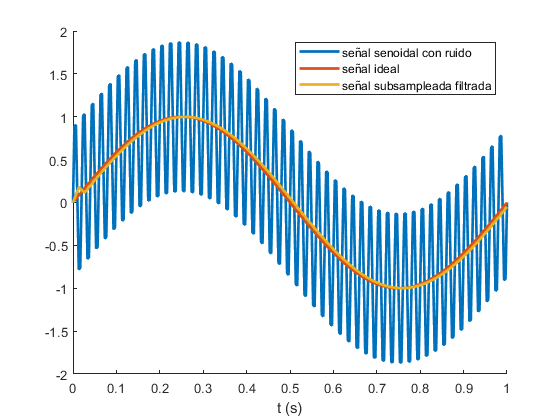

figure
hold on
plot(t, [signal_noise_xc; signal_xc], 'linewidth', 2)
plot(subsampled_t, subsampled_filt_signal_xc, 'linewidth', 2)
xlabel('t (s)')
legend('señal senoidal con ruido', 'señal ideal', 'señal subsampleada filtrada')

## Cálculo de SNR para score del filtro de onda senoidal

subsampled_signal_xc = signal_xc(1:round(fs/fs_new):end);
SNR_xc = 20*log10(rms(subsampled_signal_xc)/rms(subsampled_filt_signal_xc - subsampled_signal_xc))

SNR_xc = 25.3609

if SNR_xc < 10
    disp(['Nota Ej 1 = 4'])
elseif SNR_xc < 13
    disp(['Nota Ej 1 = 5'])
elseif SNR_xc < 16
    disp(['Nota Ej 1 = 6'])
elseif SNR_xc < 19
    disp(['Nota Ej 1 = 7'])
elseif SNR_xc < 22
    disp(['Nota Ej 1 = 8'])
else
    disp(['Nota Ej 1 = 9'])
end

Nota Ej 1 = 9


## Resultados onda senoidal

*** ¿La señal filtrada tiene mucho desfasaje? ¿distorsiona la forma? Explique sus resultados***

***Tiene un desfasaje de 3 muestras dado que el orden del filtro de media movil fue de 6. La forma no la distorsiona porque es un filtro de fase líneal con lo cual el desfase en el tiempo es constante***

## Diseño del filtro FIR onda cuadrada

lambda = 0.65

lambda = 0.6500

% b = 1-lambda;
% a = [1 -lambda];
orden = round(fs/(2*fmax))

orden = 4

b = (1/orden)*ones(1, orden);
a=1;
filtered_signal_xr = filter(b, a, signal_noise_xr);

## Polos, ceros y diagrama de bode

Realice un plot para ver ceros, polos y el diagrama de bode del filtro

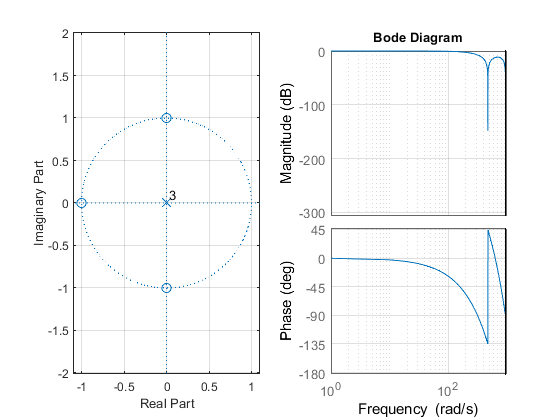

figure
subplot(1,2,1)
zplane(b,a)
grid on
subplot(1,2,2)
bode(filt(b, a, 1/sampling_rate))
grid on

## Decimación onda cuadrada

Realice una decimación de la onda filtrada, elegiendo bien la nueva frecuencia de muestreo.

subsampled_filt_signal_xr = filtered_signal_xr(1:round(fs/fs_new):end);

## Análisis en frecuencia y tiempo onda cuadrada

Haga un plot en frecuencia de para ver si eliminó las componentes que buscaba eliminar. 

## Código análisis en frecuencia

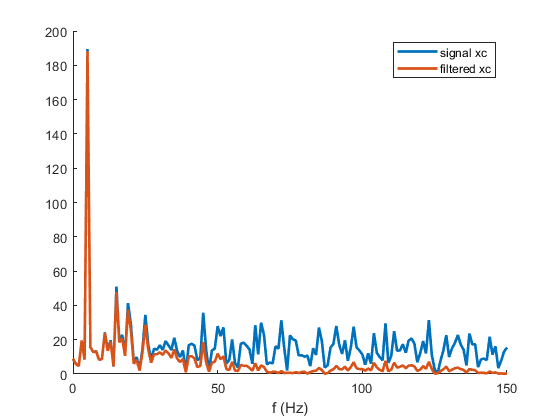

X = abs(fft(signal_noise_xr));
X_filt = abs(fft(filtered_signal_xr));
figure
hold on
plot(linspace(0, fs/2, round(length(X)/2)), X(1:round(length(X)/2)), 'linewidth', 2);
plot(linspace(0, fs/2, round(length(X_filt)/2)), X_filt(1:round(length(X_filt)/2)), 'linewidth', 2);
legend('signal xc', 'filtered xc')
xlabel('f (Hz)')

## Código análisis en tiempo

Grafique la señal original, la que tiene ruido y la filtrada para ver una compararción. 

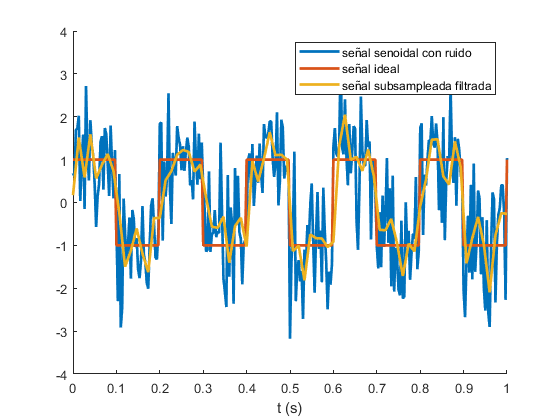

figure
hold on
plot(t, [signal_noise_xr; signal_xr], 'linewidth', 2)
plot(subsampled_t, subsampled_filt_signal_xr, 'linewidth', 2)
xlabel('t (s)')
legend('señal senoidal con ruido', 'señal ideal', 'señal subsampleada filtrada')

subsampled_signal_xr = signal_xr(1:round(fs/fs_new):end);
SNR_xr = 20*log10(rms(subsampled_signal_xr)/rms(subsampled_filt_signal_xr - subsampled_signal_xr))

SNR_xr = 4.4473

if SNR_xr < 10
    disp(['Nota Ej 1 = 4'])
elseif SNR_xr < 13
    disp(['Nota Ej 1 = 5'])
elseif SNR_xr < 16
    disp(['Nota Ej 1 = 6'])
elseif SNR_xr < 19
    disp(['Nota Ej 1 = 7'])
elseif SNR_xr < 22
    disp(['Nota Ej 1 = 8'])
else
    disp(['Nota Ej 1 = 9'])
end

Nota Ej 1 = 4


## Resultados onda senoidal

*** ¿La señal filtrada tiene mucho desfasaje? ¿distorsiona la forma? Explique sus resultados.***

***No tiene demasiado desfasaje porque el filtro no es de orden alto. La forma esta distorsionada, pero aun se preserva la información.***

## ADC

***¿Cuántos bits tendría que tener el ADC de cada canal en función del ruido observado suponiendo 1 bit de guarda para el ruido?***

***B_noise*6.02 = SNRADC-SNRSEÑAL.***

***Usando esta fórmula. Tendríamos.***

bnoise = 1;
snr_adc = 6.02*bnoise + max(SNR_xr, SNR_xc);
% Asumiendo una señal senoidal de excursión completa necesitamos
N = ceil((snr_adc - 1.76)/6.02)

N = 5

Entonces se podría usar un ADC de 10 bits por ejemplo. O bien un ADC de mas de 5.

## Análisis de aritmética punto fijo o flotante 

***Sugiera una representación en punto fijo que sea óptima para almacenar la señal senoidal, sin la presencia del ruido.***

max(signal_xc)

ans = 1

min(signal_xc)

ans = -1

prec = min(abs(diff(signal_xc)))

prec = 2.1932e-04

log2(prec)

ans = -12.1547

Con una representación Q.15 sería suficiente y adecuado. Se alcanza a representar el mínimo valor de la señal y hasta casi el máximo con suficiente precisión para representar le cambio de la señal, osea, la variació entre muestras sucesivas.

## `Elegir `una` opción`

***Teniendo toda la información reunida hasta ahora, ¿qué representación usaría para el diseño del filtro para optimizar recursos?***